# Sistemas de Visión Artificial

# **Práctica 2. Técnicas Básicas de Procesamiento de Imágenes**

**Autor(es): Patricia Cuesta Ruiz y Laura Mambrilla Moreno**

**Fecha:**

El objetivo principal de esta práctica es familiarizarse con las **técnicas básicas de procesamiento de imágenes mediante la *****Image Processing Toolbox***** de Matlab**. Para ello se proponen ejercicios sobre operaciones geométricas, ecualización del histograma, diseño e implementación de filtros y filtrado de imágenes en el dominio del espacio, mediante máscaras de convolución. La mayoría de las técnicas de mejora se aplican a imágenes de intensidad (escala de grises). Para mejorar una imagen RGB, trabajaremos, normalmente, con las matrices de las componentes rojo, verde y azul separadamente.

**La memoria de la práctica se completará en este mismo fichero .mlx**, añadiendo el nombre del autor/autores del grupo, fecha, e insertando el código y los comentarios pertinentes en cada apartado. Las distintas partes serán secciones independientes (deberá insertar "section break" entre ellas), y se visualizarán los resultados conjuntamente con subplot cuando sea conveniente. 

La **calificación **se basará en la corrección del código y de los comentarios (la explicación del código, justificación de los resultados y conclusiones sobre el funcionamiento de cada algoritmo, comparación entre distintos resultados, etc). Por esta razón es imprescindible añadir todas las justificaciones, comparaciones, etc. que se solicitan en el enunciado.

Se valorará positivamente la **ampliación** con las explicaciones que considere oportunas, pruebas adicionales (modificando parámetros, utilizando otras imágenes que resalten algún efecto del procesamiento, etc.), descripción de problemas surgidos en la ejecución de la práctica y solución proporcionada, etc. 

La **entrega **se realizará en el Aula Virtual de la asignatura: Contenidos --> Entregables --> Práctica 2.

clc;
clear all; %#ok<CLALL> 
close all;

Implemente el siguiente código, visualice los resultados obtenidos y justifíquelos:

1.	Utilice *imageinfo *para averiguar el formato (RGB, mapa de colores indexado, etc.) de una imagen en color (‘canoe.tif’, 'peppers.png',…) y ábrala utilizando las variables adecuadas (J, X, map, etc...).

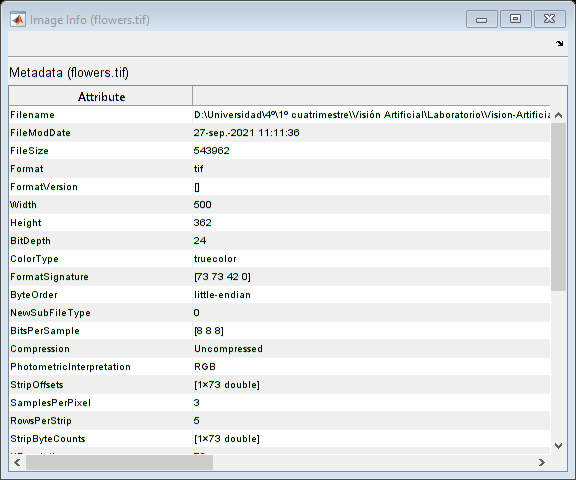

imageinfo('flowers.tif'); % comprobamos la información de la imagen

ini_I = imread('flowers.tif'); % leemos la imagen y la guardamos en una variable

2.	Visualice la imagen que acaba de leer.

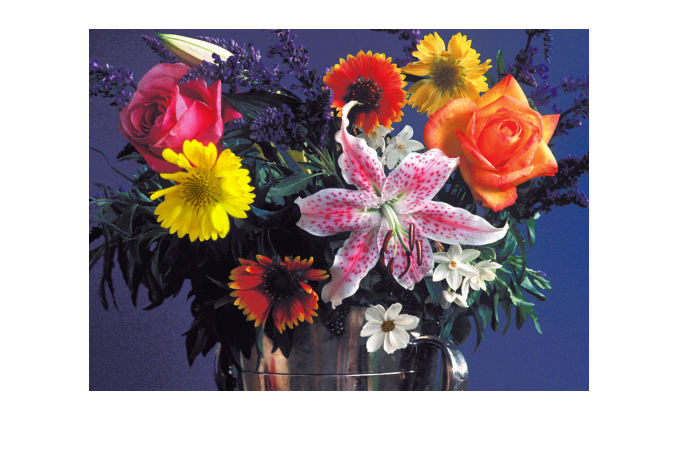

imshow(ini_I);                 % mostramos la imagen

3.	Convierta la imagen anterior en una imagen en escala de grises y almacénela en un array llamado I. Indique el rango de valores en los que se cuantifica la luminancia (niveles de gris mínimo y máximo) de la imagen resultante.

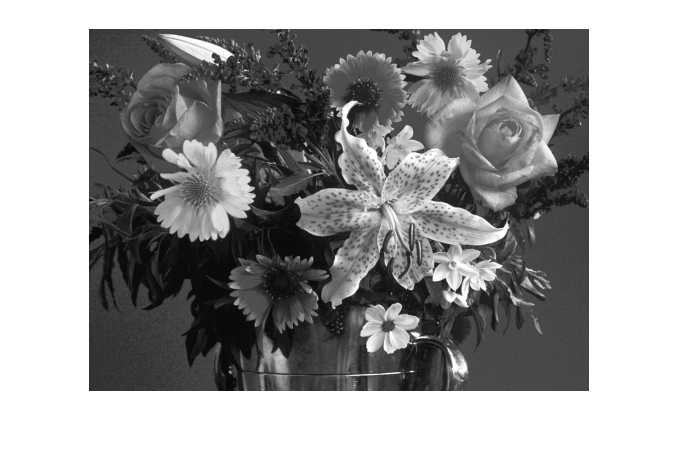

I = rgb2gray(ini_I);
imshow(I);

max_I = max(I(:)) 

max_I = uint8
255

min_I = min(I(:))

min_I = uint8
8

4.	Averigüe las dimensiones de nuestra imagen I (filas x columnas).

size_I = size(I);
rows_I = size_I(1)    % guardamos el primer valor del array size_I, que corresponde con las filas de I

rows_I = 362

columns_I = size_I(2) % guardamos el segundo valor del array size_I, que corresponde con las columnas de I

columns_I = 500

5.	Muestre el histograma de la imagen I.

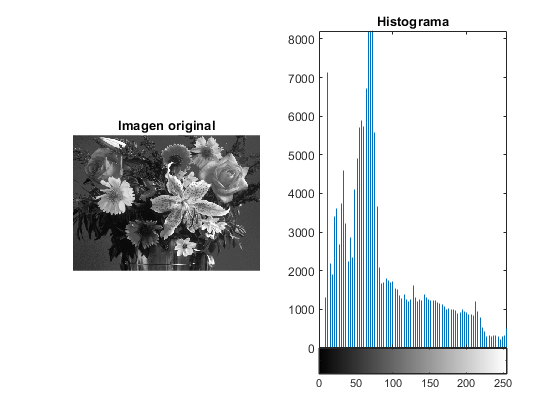

figure;
subplot(1,2,1); imshow(I);     title('Imagen original');
subplot(1,2,2); imhist(I, 85); title('Histograma');

6.	Modifique el brillo y el contraste de la imagen I y visualice las imágenes resultantes y sus histogramas.

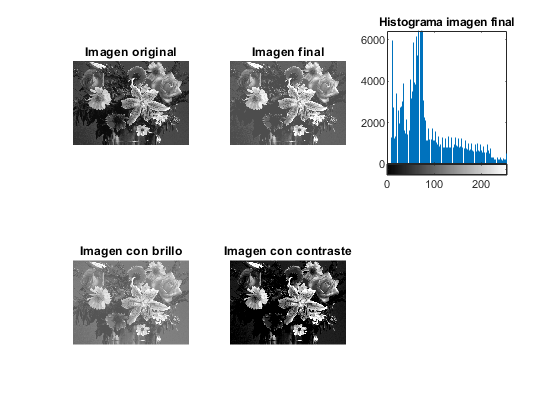

I_double = im2double(I);                % pasamos la imagen I a tipo double

% imadjust(imagen, contraste, brillo)
I_c = imadjust(I, [0.2 0.9], []);       % modificamos el contraste
I_b = imadjust(I, [], [0.3 1]);         % modificamos el brillo
I_ad = imadjust(I, [0.2 0.9], [0.3 1]); % guardamos la imagen final con el contraste y brillo modificados

figure;
subplot(2,3,1); imshow(I);      title('Imagen original');
subplot(2,3,2); imshow(I_ad);   title('Imagen final');
subplot(2,3,3); imhist(I, 110); title('Histograma imagen final');
subplot(2,3,4); imshow(I_b);    title('Imagen con brillo');
subplot(2,3,5); imshow(I_c);    title('Imagen con contraste');

7.	Realice una binarización de la imagen I con un umbral cuyo valor sea aproximadamente la mitad de su rango de grises y visualice el resultado.

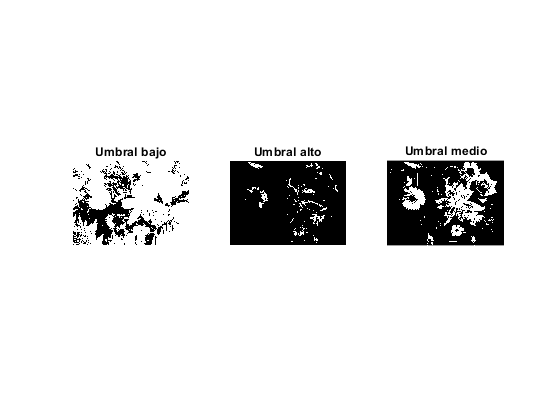

% im2bw(imagen, umbral nivel de grises);
I_bw1 = im2bw(I, 0.2); % si ponemos un valor bajo para el umbral, serán pocos los niveles de gris que pasen a negro
I_bw2 = im2bw(I, 0.8); % si ponemos un valor alto para el umbral, serán pocos los niveles de gris que pasen a blanco
I_bw3 = im2bw(I, 0.5); % hemos usado el valor 0.5

figure;
subplot(1,3,1); imshow(I_bw1); title('Umbral bajo');
subplot(1,3,2); imshow(I_bw2); title('Umbral alto');
subplot(1,3,3); imshow(I_bw3); title('Umbral medio');

8.	Obtenga el negativo de la imagen I obtenida en el punto 3.

Hay dos formas distintas de obtener el negativo de la imagen:

- neg = 255 - I : se resta 255 a los valores de gris de la imagen para obtener el valor contrario.     Ej: 255 - 45 = 210, lo que antes era un gris muy oscuro ha pasado a ser un gris bastante claro.

- neg = incomplement(I) : función que obtiene el negativo de la imagen.

Con ambas se obtiene el mismo resultado.

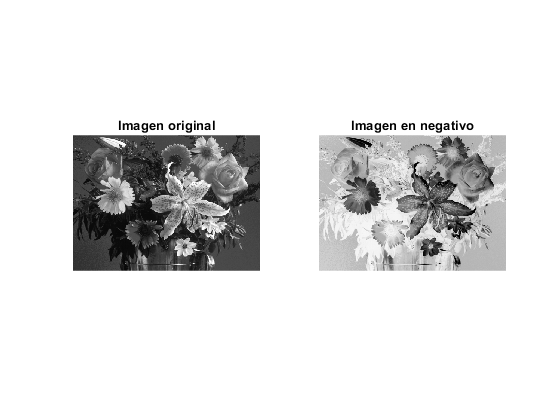

I_neg = 255 - I;

figure;
subplot(1,2,1); imshow(I);     title('Imagen original');
subplot(1,2,2); imshow(I_neg); title('Imagen en negativo');

9.	Obtenga y muestre tres versiones ruidosas de la imagen I: 

    (a) con ruido de distribución uniforme ‘speckle’, 

    (b) con ruido de tipo ‘sal y pimienta’ de densidad de ruido 5%, 

    (c) con ruido de tipo gaussiano de media cero y varianza 0.01.

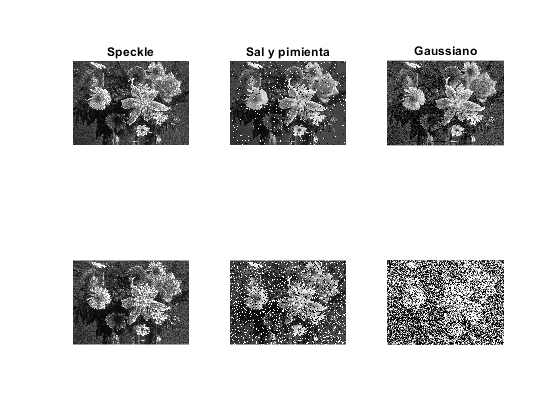

% Pruebas
I_speckle1 = imnoise(I, 'speckle');
I_saltpepper1 = imnoise(I, 'salt & pepper');
I_gaussian1 = imnoise(I, 'gaussian');
I_speckle2 = imnoise(I,'speckle', 0.08);
I_saltpepper2 = imnoise(I, 'salt & pepper', 0.2);
I_gaussian3 = imnoise(I, 'gaussian', 0.15, 0.3);

figure;
subplot(2,3,1); imshow(I_speckle1);    title('Speckle');
subplot(2,3,2); imshow(I_saltpepper1); title('Sal y pimienta');
subplot(2,3,3); imshow(I_gaussian1);   title('Gaussiano');
subplot(2,3,4); imshow(I_speckle2);
subplot(2,3,5); imshow(I_saltpepper2); 
subplot(2,3,6); imshow(I_gaussian3); 

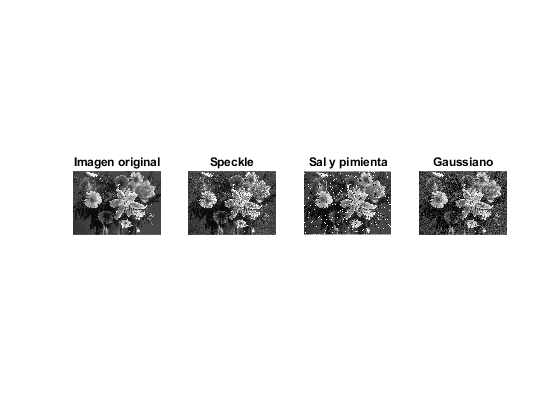

% A
I_speckle = imnoise(I, 'speckle');
% B
I_saltpepper = imnoise(I, 'salt & pepper', 0.05);
% C
I_gaussian = imnoise(I, 'gaussian', 0, 0.01);

figure;
subplot(1,4,1); imshow(I);            title('Imagen original');
subplot(1,4,2); imshow(I_speckle);    title('Speckle');
subplot(1,4,3); imshow(I_saltpepper); title('Sal y pimienta');
subplot(1,4,4); imshow(I_gaussian);   title('Gaussiano');

10.	Partiendo de la imagen contaminada con ruido gaussiano anterior, fíltrela utilizando la media del entorno de vecindad, primero con un entorno de vecindad de 3x3 y luego con uno de 5x5, comparando los resultados obtenidos. Justifique sus conclusiones.

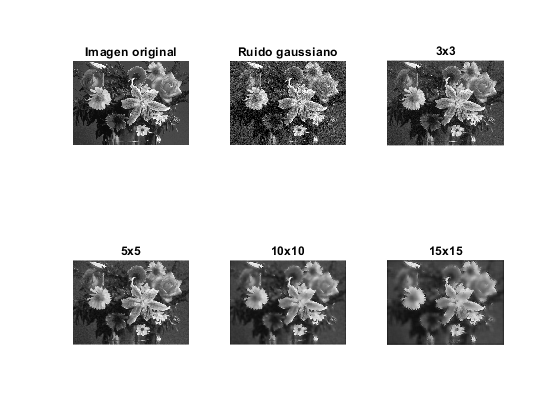

I_wiener3 = wiener2(I_gaussian, [3 3]);
I_wiener5 = wiener2(I_gaussian, [5 5]);
I_wiener10 = wiener2(I_gaussian, [10 10]);
I_wiener15 = wiener2(I_gaussian, [15 15]);

figure;
subplot(2,3,1); imshow(I);          title('Imagen original');
subplot(2,3,2); imshow(I_gaussian); title('Ruido gaussiano');
subplot(2,3,3); imshow(I_wiener3);  title('3x3');
subplot(2,3,4); imshow(I_wiener5);  title('5x5');
subplot(2,3,5); imshow(I_wiener10); title('10x10');
subplot(2,3,6); imshow(I_wiener15); title('15x15');

**Comparando ambos resultados, observamos que al usar un filtro con un entorno de vecindad de 3x3 la imagen no pierde mucha nitidez, pero sigue habiéndo mucho ruido gaussiano. En cambio, al usar un filtro de 5x5 se pierde nitidez pero aparece menos ruido en la imagen de salida.**

11.	Lea la imagen venas.tif y rótela un ángulo de 50 grados (por ejemplo), utilizando los métodos de interpolación nearest y bicubic (parámetros de la función imrotate). Aumente las imágenes lo suficiente para ver las diferencias entre ambos resultados y compárelos.

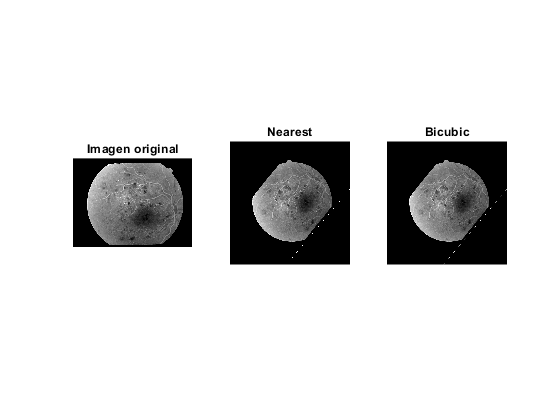

[J, map] = imread('venas.tif');       % carga la imagen indexada en [X, map]
J_rot1 = imrotate(J, 50, 'nearest');
J_rot2 = imrotate(J, 50, 'bicubic');

figure;
subplot(1,3,1); imshow(J, map);      title('Imagen original');
subplot(1,3,2); imshow(J_rot1, map); title('Nearest');
subplot(1,3,3); imshow(J_rot2, map); title('Bicubic');

**El método de interpolación de vecino más cercano (*****nearest*****) asigna al píxel de salida el valor del píxel en el que se encuentra el punto, sin tener en cuenta otros píxeles. Tiene menor coste computacional, pero podemos observar que la superficie es abrupta, mostrando dientes de sierra al cambiar el ángulo respecto a la imagen original.**

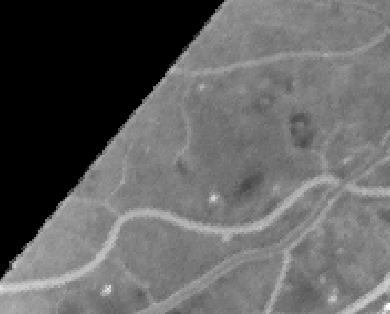

**El método de interpolación bicúbica calcula el valor del píxel de salida haciendo un promedio ponderado de píxeles en la vecindad 4 por 4 más cercana. Aunque su coste computacional es mayor, como resultado obtenemos una superficie más homogénea y suave respecto al método anterior.**

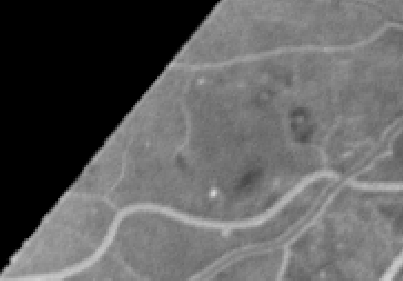

12.	A partir de la imagen original blood1.tif, obtenga 16 imágenes diferentes con ruido gaussiano de media cero y varianza 0.05. Utilizando la función *imwrite*, guárdelas en ficheros con sus respectivos nombres (ruidosa1.bmp, …, ruidosa16.bmp).

V = imread('blood1.tif');

Vx1= imnoise(V, 'gaussian', 0, 0.05);
Vx2= imnoise(V, 'gaussian', 0, 0.05);
Vx3= imnoise(V, 'gaussian', 0, 0.05);
Vx4= imnoise(V, 'gaussian', 0, 0.05);
Vx5= imnoise(V, 'gaussian', 0, 0.05);
Vx6= imnoise(V, 'gaussian', 0, 0.05);
Vx7= imnoise(V, 'gaussian', 0, 0.05);
Vx8= imnoise(V, 'gaussian', 0, 0.05);
Vx9= imnoise(V, 'gaussian', 0, 0.05);
Vx10= imnoise(V, 'gaussian', 0, 0.05);
Vx11= imnoise(V, 'gaussian', 0, 0.05);
Vx12= imnoise(V, 'gaussian', 0, 0.05);
Vx13= imnoise(V, 'gaussian', 0, 0.05);
Vx14= imnoise(V, 'gaussian', 0, 0.05);
Vx15= imnoise(V, 'gaussian', 0, 0.05);
Vx16= imnoise(V, 'gaussian', 0, 0.05);

imwrite(Vx1, 'ruidosa1.bmp');
imwrite(Vx2, 'ruidosa2.bmp');
imwrite(Vx3, 'ruidosa3.bmp');
imwrite(Vx4, 'ruidosa4.bmp');
imwrite(Vx5, 'ruidosa5.bmp');
imwrite(Vx6, 'ruidosa6.bmp');
imwrite(Vx7, 'ruidosa7.bmp');
imwrite(Vx8, 'ruidosa8.bmp');
imwrite(Vx9, 'ruidosa9.bmp');
imwrite(Vx10, 'ruidosa10.bmp');
imwrite(Vx11, 'ruidosa11.bmp');
imwrite(Vx12, 'ruidosa12.bmp');
imwrite(Vx13, 'ruidosa13.bmp');
imwrite(Vx14, 'ruidosa14.bmp');
imwrite(Vx15, 'ruidosa15.bmp');
imwrite(Vx16, 'ruidosa16.bmp');

13.	Realice pruebas de filtrado de ruido usando la técnica de promediado de imágenes sobre las imágenes creadas en el punto anterior. Para ello, promedie en primer lugar con 4 imágenes ruidosas, luego con 8 y, finalmente, con las 16. Compare visualmente los resultados y coméntelos.

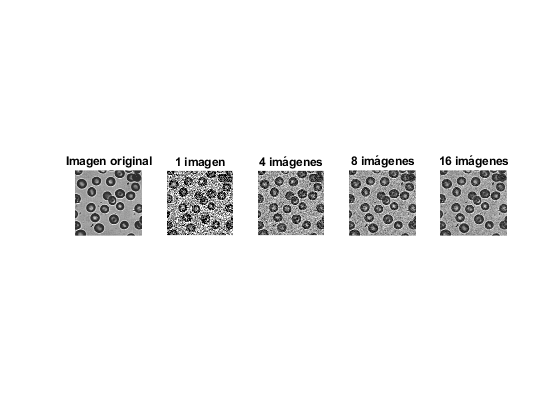

mean4 = (Vx1/4) + (Vx2/4) + (Vx3/4) + (Vx4/4);
mean8 = (Vx1/8) + (Vx2/8) + (Vx3/8) + (Vx4/8) + (Vx5/8) + (Vx6/8) + (Vx7/8) + (Vx8/8);
mean16 = (Vx1/16) + (Vx2/16) + (Vx3/16) + (Vx4/16) + (Vx5/16) + (Vx6/16) + (Vx7/16) + (Vx8/16) + (Vx9/16) + (Vx10/16) + (Vx11/16) + (Vx12/16) + (Vx13/16) + (Vx14/16) + (Vx15/16) + (Vx16/16);

figure;
subplot(1,5,1); imshow(V);      title('Imagen original')
subplot(1,5,2); imshow(Vx1);    title('1 imagen');
subplot(1,5,3); imshow(mean4);  title('4 imágenes');
subplot(1,5,4); imshow(mean8);  title('8 imágenes');
subplot(1,5,5); imshow(mean16); title('16 imágenes');

**Como se puede observar, cuantas más imágenes promediemos, menor ruido habrá en la imagen resultante, siempre y cuando las imágenes sean exáctamente iguales.**

14.	Utilizando la imagen P2gris.jpg, compuesta únicamente por un fondo grisáceo de luminancia intermedia, complete los siguientes pasos:

- cargue la imagen, conviértala a escala de grises y muestre su histograma,

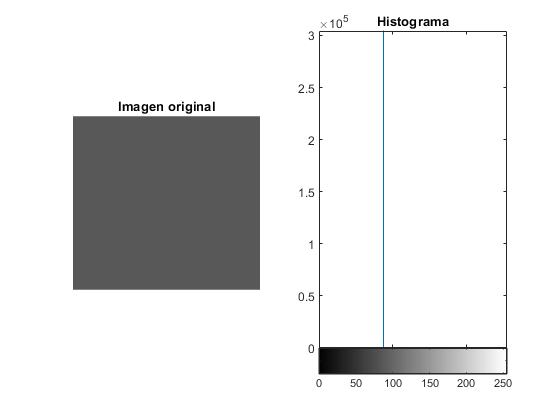

W = imread('P2gris.jpg');
W_gray = rgb2gray(W);

figure;
subplot(1,2,1); imshow(W_gray);     title('Imagen original');
subplot(1,2,2); imhist(W_gray, 85); title('Histograma');

- contamine con ruido speckle la imagen de grises y almacene el resultado en otro fichero de imagen,

W_speckle = imnoise(W, 'speckle');
imwrite(W_speckle, 'P2gris_ruido.jpg');

- muestre y observe el histograma de la imagen ruidosa y confirme que el ruido tiene una distribución uniforme,

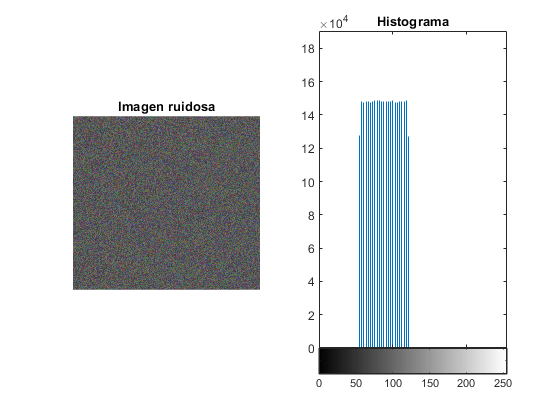

figure;
subplot(1,2,1); imshow(W_speckle);     title('Imagen ruidosa');
subplot(1,2,2); imhist(W_speckle, 85); title('Histograma');

**Como se puede observar en el histograma, tiene una distribución uniforme.**

- consulte la ayuda del comando imnoise, para ver cómo se puede cambiar la varianza del ruido, contamine la imagen original con ruido speckle con diferentes varianzas, muestre y observe qué ocurre con los histogramas de las distintas imágenes ruidosas generadas.

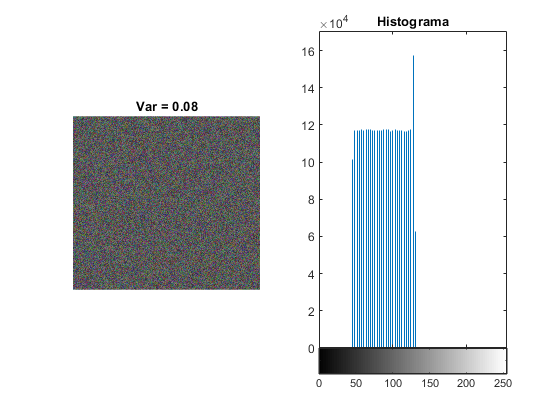

% imnoise(imagen, modo de ruido, varianza);
W_speckle1 = imnoise(W, 'speckle', 0.08);

figure;
subplot(1,2,1); imshow(W_speckle1);     title('Var = 0.08');
subplot(1,2,2); imhist(W_speckle1, 85); title('Histograma');

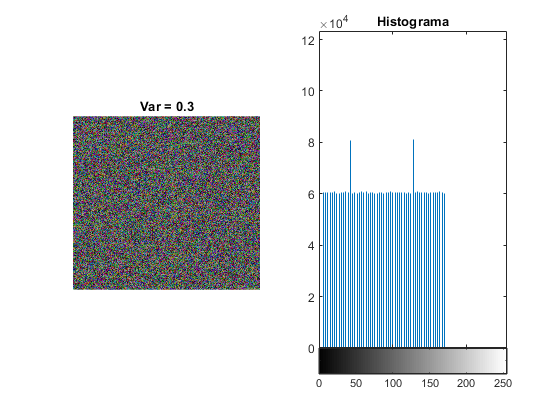

W_speckle2 = imnoise(W, 'speckle', 0.3);

figure;
subplot(1,2,1); imshow(W_speckle2);     title('Var = 0.3');
subplot(1,2,2); imhist(W_speckle2, 85); title('Histograma');

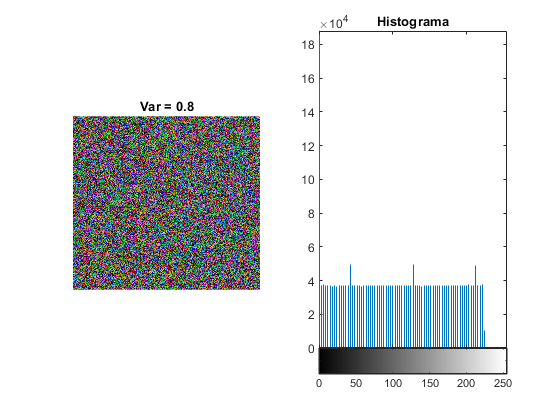

W_speckle3 = imnoise(W, 'speckle', 0.8);

figure;
subplot(1,2,1); imshow(W_speckle3);     title('Var = 0.8');
subplot(1,2,2); imhist(W_speckle3, 85); title('Histograma');

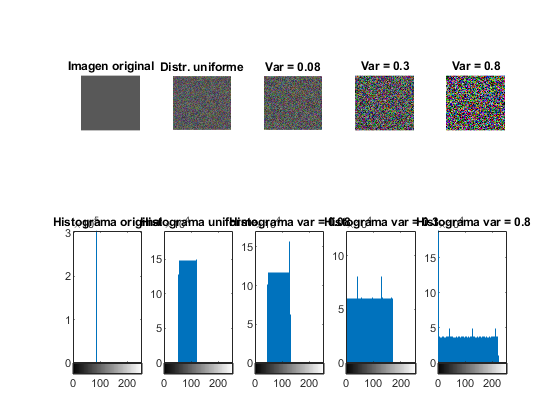

figure;
subplot(2,5,1);  imshow(W_gray);         title('Imagen original')
subplot(2,5,2);  imshow(W_speckle);      title('Distr. uniforme')
subplot(2,5,3);  imshow(W_speckle1);     title('Var = 0.08');
subplot(2,5,4);  imshow(W_speckle2);     title('Var = 0.3');
subplot(2,5,5);  imshow(W_speckle3);     title('Var = 0.8');
subplot(2,5,6);  imhist(W_gray, 85);     title('Histograma original');
subplot(2,5,7);  imhist(W_speckle, 85);  title('Histograma uniforme');
subplot(2,5,8);  imhist(W_speckle1, 85); title('Histograma var = 0.08');
subplot(2,5,9);  imhist(W_speckle2, 85); title('Histograma var = 0.3');
subplot(2,5,10); imhist(W_speckle3, 85); title('Histograma var = 0.8');

**A medida que la varianza aumenta, observamos que los valores de los histogramas abarcan menos en el eje de ordenadas y más en el de abscisas. **

**Además, al añadir ruido *****speckle***** a la imagen con la función *****imnoise***** devuelve una imagen RGB, ya que añade valores aleatorios a las distintas matrices de las componentes R, G y B. Por esto, aunque la imagen que tratamos esté en escala de grises, al aplicar el ruido obtenemos imágenes RGB y a medida que aumentamos el valor de la varianza, aumentan los colores que aparecen.**

15.	Busque una imagen oscura y con poco contraste, o créela a partir de una fotografía (multiplicando por 0.1 o 0.2 sus niveles de gris). A continuación, visualice dicha imagen y su histograma. Finalmente, aplique el logaritmo a dicha imagen, calculando previamente el valor óptimo de K, para asegurar que el nivel máximo de gris a la salida sea el máximo posible. Visualice la imagen resultante y observe la mejora obtenida. Pruebe utilizando valores de K diferentes al calculado.

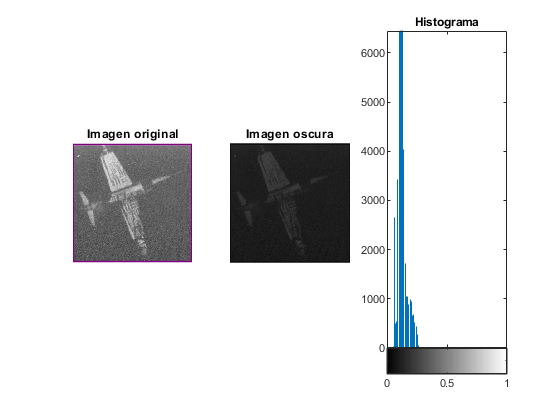

L = imread('avión2.jpg');
L_gray = im2double(rgb2gray(L));
L_gray1 = L_gray * 0.3;               % multiplicamos por 0.3 sus niveles de gris para obtener una imagen más oscura y con poco contraste

figure;
subplot(1,3,1); imshow(L);            title('Imagen original');
subplot(1,3,2); imshow(L_gray1);      title('Imagen oscura');
subplot(1,3,3); imhist(L_gray1, 100); title('Histograma');

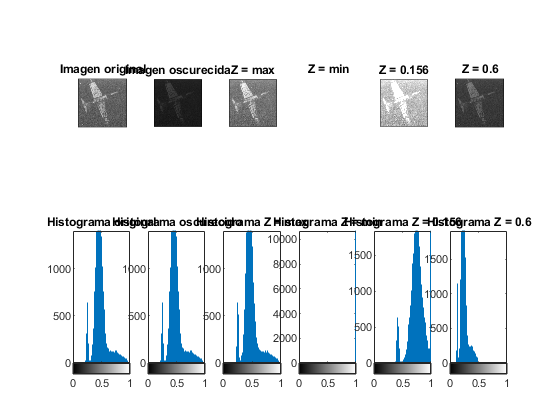

Z = max(L_gray1(:));                  % valor óptimo
klog = 1/log10(1 + Z);
logarithm = klog * log10(1 + L_gray1);

Z1 = 0.156;                           % valor de prueba elegido aleatoriamente
klog1 = 1/log10(1 + Z1);
logarithm1 = klog1 * log10(1 + L_gray1);

Z2 = 0.6;                             % valor de prueba elegido aleatoriamente
klog2 = 1/log10(1 + Z2);
logarithm2 = klog2 * log10(1 + L_gray1);

Z3 = min(L_gray1(:));                 % valor de prueba 
klog3 = 1/log10(1 + Z3);
logarithm3 = klog3 * log10(1 + L_gray1);

figure;
subplot(2,6,1);  imshow(L_gray);     title('Imagen original');
subplot(2,6,2);  imshow(L_gray1);    title('Imagen oscurecida');
subplot(2,6,3);  imshow(logarithm);  title('Z = max');
subplot(2,6,4);  imshow(logarithm3); title('Z = min');
subplot(2,6,5);  imshow(logarithm1); title('Z = 0.156');
subplot(2,6,6);  imshow(logarithm2); title('Z = 0.6');
subplot(2,6,7);  imhist(logarithm);  title('Histograma original');
subplot(2,6,8);  imhist(logarithm);  title('Histograma oscurecido');
subplot(2,6,9);  imhist(logarithm);  title('Histograma Z = max');
subplot(2,6,10); imhist(logarithm3); title('Histograma Z = min');
subplot(2,6,11); imhist(logarithm1); title('Histograma Z = 0.156');
subplot(2,6,12); imhist(logarithm2); title('Histograma Z = 0.6');

16.	Cargue la imagen bazo.bmp y muestre su histograma. Compruebe que se trata de una imagen con poco contraste. Convierta la imagen a escala de grises y luego ecualice su histograma uniformemente. Visualice la imagen resultante y su histograma y comente las diferencias con la imagen original.

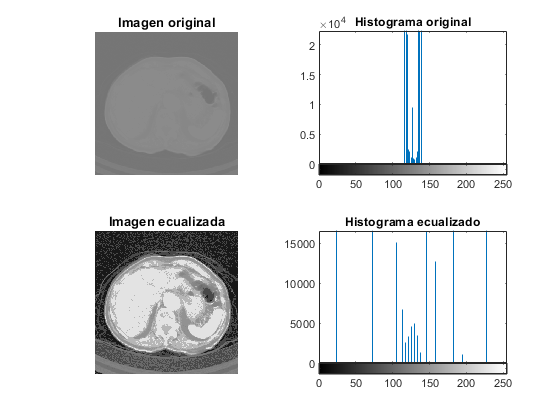

[M, map] = imread('bazo.bmp');
M_gray = ind2gray(M, map);
M_gray_eq = histeq(M_gray);     % ecualización de la imagen

figure;
subplot(2,2,1); imshow(M);         title('Imagen original');
subplot(2,2,3); imshow(M_gray_eq); title('Imagen ecualizada');
subplot(2,2,2); imhist(M, 150);    title('Histograma original');   
subplot(2,2,4); imhist(M_gray_eq); title('Histograma ecualizado');

**Los niveles de gris se concentran en un rango muy pequeño del histograma, por lo que la imagen inicial se puede apreciar que tiene poco contraste, pero al ecualizarlo y distrubuir uniformemente los valores del histograma se distinguen perfectamente los distintos elementos de la imagen.**

17.	Disminuya el brillo de la imagen bazo.bmp hasta que el nivel de gris más bajo sea 0 y realice sobre esa imagen una corrección gamma. Pruebe con distintos valores de gamma y analice el efecto de cada uno sobre la imagen de salida.

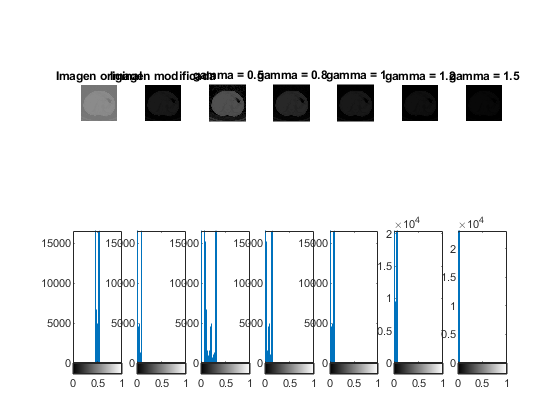

M_double = im2double(M_gray);    % pasamos la imagen I a tipo double
% max(M_double(:))
% min(M_double(:))
M_bright = imadjust(M_double, [min(M_double(:)) max(M_double(:))], [0 0.1]);  % modificamos el brillo 
M_gamma1 = imadjust(M_bright, [], [], 0.5);
M_gamma2 = imadjust(M_bright, [], [], 0.8);
M_gamma3 = imadjust(M_bright, [], [], 1);
M_gamma4 = imadjust(M_bright, [], [], 1.2);
M_gamma5 = imadjust(M_bright, [], [], 1.5);

figure;
subplot(2,7,1);  imshow(M_double); title('Imagen original');
subplot(2,7,8);  imhist(M_double);
subplot(2,7,2);  imshow(M_bright); title('Imagen modificada');
subplot(2,7,9);  imhist(M_bright);
subplot(2,7,3);  imshow(M_gamma1); title('gamma = 0.5');
subplot(2,7,10); imhist(M_gamma1);
subplot(2,7,4);  imshow(M_gamma2); title('gamma = 0.8');
subplot(2,7,11); imhist(M_gamma2);
subplot(2,7,5);  imshow(M_gamma3); title('gamma = 1');
subplot(2,7,12); imhist(M_gamma3);
subplot(2,7,6);  imshow(M_gamma4); title('gamma = 1.2');
subplot(2,7,13); imhist(M_gamma4);
subplot(2,7,7);  imshow(M_gamma5); title('gamma = 1.5');
subplot(2,7,14); imhist(M_gamma5);

**Cuando gamma es menor que uno (*****M_gamma1*****, *****M_gamma2*****), aumenta el contraste en zonas oscuras y cuando gamma es mayor que uno (*****M_gamma4*****, *****M_gamma5*****), aumenta el contraste en zonas claras.**

**Si comparamos la imagen con el brillo modificado (sobre la que aplicamos la corrección gamma) con *****M_gamma3 *****(en la que el valor del parámetro correspondiente a la corrección gamma es 1), podemos observar que son idénticas, por lo que concluimos que 1 es un valor de gamma neutral.**

**Además, ya que sobre la imagen *****bazo.bmp***** no se aprecia demasiado bien la corrección de gamma por tener un rango bastante pequeño de niveles de grises, hemos cogido otra imagen de las proporcionadas para la práctica y le hemos aplicado distintas correcciones de gamma. **

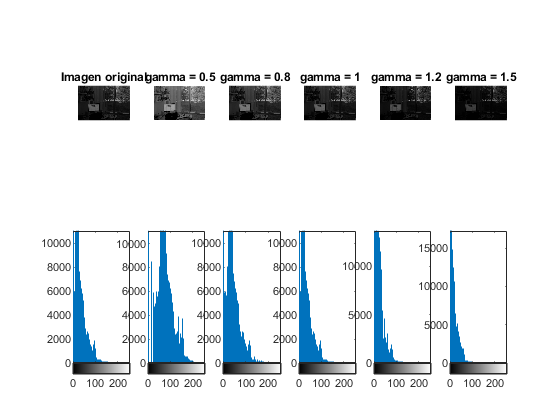

A = imread('office_2.jpg');
A_gray = rgb2gray(A);
A_gamma1 = imadjust(A_gray, [], [], 0.5);
A_gamma2 = imadjust(A_gray, [], [], 0.8);
A_gamma3 = imadjust(A_gray, [], [], 1);
A_gamma4 = imadjust(A_gray, [], [], 1.2);
A_gamma5 = imadjust(A_gray, [], [], 1.5);

figure;
subplot(2,6,1);  imshow(A_gray);   title('Imagen original');
subplot(2,6,7);  imhist(A_gray);
subplot(2,6,2);  imshow(A_gamma1); title('gamma = 0.5');
subplot(2,6,8);  imhist(A_gamma1);
subplot(2,6,3);  imshow(A_gamma2); title('gamma = 0.8');
subplot(2,6,9);  imhist(A_gamma2);
subplot(2,6,4);  imshow(A_gamma3); title('gamma = 1');
subplot(2,6,10); imhist(A_gamma3);
subplot(2,6,5);  imshow(A_gamma4); title('gamma = 1.2');
subplot(2,6,11); imhist(A_gamma4);
subplot(2,6,6);  imshow(A_gamma5); title('gamma = 1.5');
subplot(2,6,12); imhist(A_gamma5);

**En las imágenes resultantes de este caso se puede apreciar de forma adecuada que cuando el gamma es menor que 1, aumenta el contraste en las zonas oscuras y pasan a ser más claras y visibles. **

18.	Efectúe las siguientes operaciones, relacionadas con la mejora de imágenes: 

        18.1.	Cargue y visualice la imagen ‘pout.tif’.

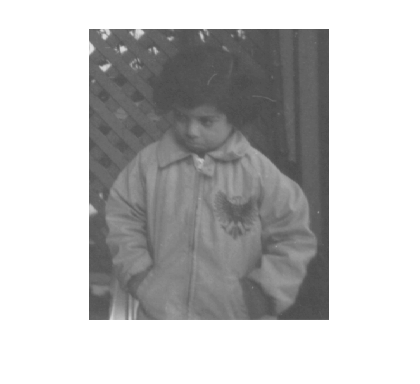

N = imread('pout.tif');

figure;
imshow(N);

        18.2.	Compruebe los principales parámetros de la imagen con el comando *imfinfo*.

info = imfinfo('pout.tif')

info = struct with fields:
                     Filename: 'D:\Universidad\4º\1º cuatrimestre\Visión Artificial\Laboratorio\Vision-Artificial_Github\Práctica 2\imágenes_p2\pout.tif'
                  FileModDate: '27-sep.-2021 11:11:36'
                     FileSize: 69004
                       Format: 'tif'
                FormatVersion: []
                        Width: 240
                       Height: 291
                     BitDepth: 8
                    ColorType: 'grayscale'
              FormatSignature: [73 73 42 0]
                    ByteOrder: 'little-endian'
               NewSubFileType: 0
                BitsPerSample: 8
                  Compression: 'PackBits'
    PhotometricInterpretation: 'BlackIsZero'
                 StripOffsets: [8 7984 15936 23976 32089 40234 48335 56370 64301]
              SamplesPerPixel: 1
                 RowsPerStrip: 34
              StripByteCounts: [7976 7952 8040 8113 8145 8101 8035 7931 4452]
                  XResolution: 72
     

        18.3.	Muestre el histograma de la misma.

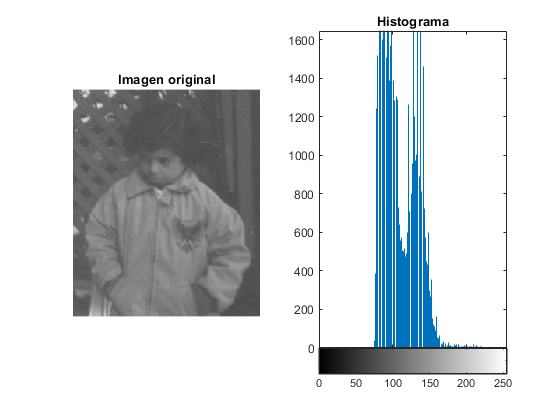

figure;
subplot(1,2,1); imshow(N); title('Imagen original')
subplot(1,2,2); imhist(N); title('Histograma')

        18.4.	Ecualice el histograma y muestre la imagen y el histograma después de la ecualización. 

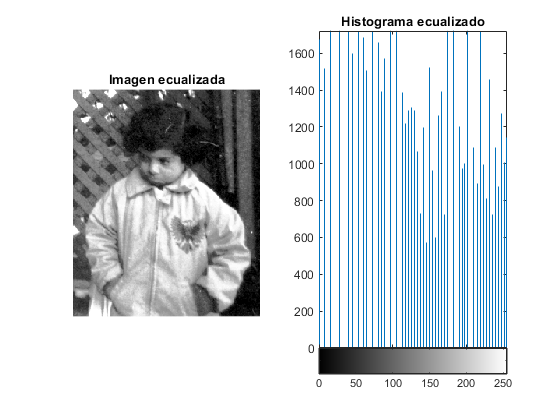

N_eq = histeq(N);     % ecualización de la imagen

figure;
subplot(1,2,1); imshow(N_eq); title('Imagen ecualizada')
subplot(1,2,2); imhist(N_eq); title('Histograma ecualizado')

        18.5.	Almacene la imagen ecualizada en un fichero jpeg utilizando el comando imwrite.

imwrite(N_eq, 'nina_eq.jpeg');

        18.6.	Sobre la imagen original: Optimice el contraste al máximo, y muestre el histograma de la imagen de salida y su FFT.

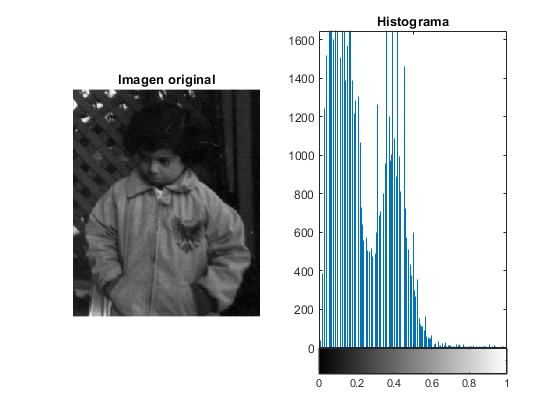

N_double = im2double(N);
N_c = imadjust(N_double, [min(min(N_double)) max(max(N_double))], [0 1]); 
N_FFT = fftshift(fft2(N_c));

figure;
subplot(1,2,1); imshow(N_c); title('Imagen original');
subplot(1,2,2); imhist(N_c); title('Histograma');

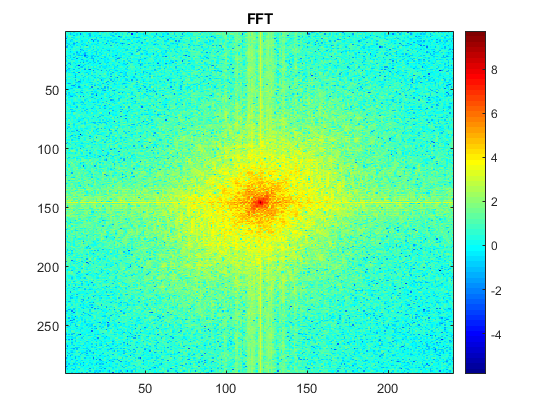

figure;
colormap(jet(64)); imagesc(log(abs(N_FFT))); colorbar; title('FFT');

        18.7.	Añada ruido gaussiano, muestre el histograma de la imagen con ruido, obtenga su FFT y muéstrela.

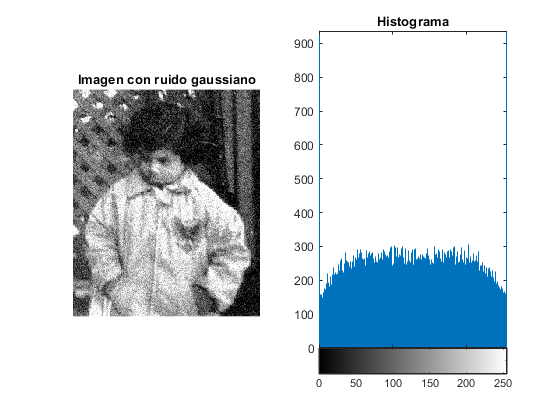

N_gaussian = imnoise(N_eq, 'gaussian');
N_gaussian_FFT = fftshift(fft2(N_gaussian));

figure;
subplot(1,2,1); imshow(N_gaussian); title('Imagen con ruido gaussiano');
subplot(1,2,2); imhist(N_gaussian); title('Histograma');

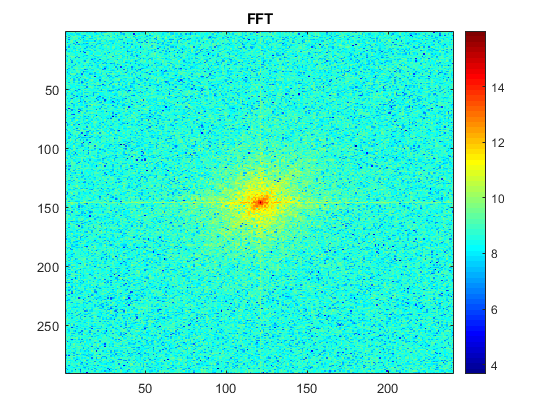

figure;
colormap(jet(64)); imagesc(log(abs(N_gaussian_FFT))); colorbar; title('FFT');

        18.8.	Aplique los siguientes filtros a la imagen con ruido y compare las imágenes de salida:

-    un filtro Wiener en el dominio del espacio,

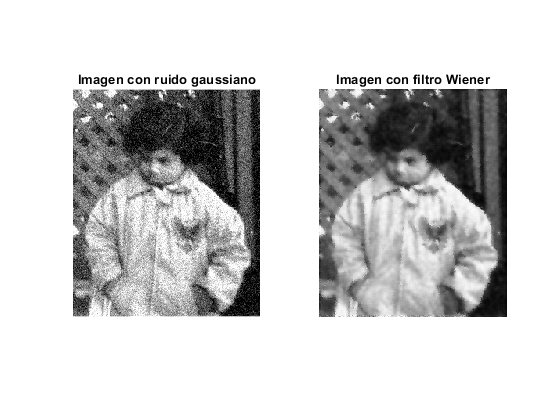

N_wiener = wiener2(N_gaussian, [5 5]);

figure;
subplot(1,2,1); imshow(N_gaussian); title('Imagen con ruido gaussiano');
subplot(1,2,2); imshow(N_wiener);   title('Imagen con filtro Wiener');

-    un filtro paso bajo en el dominio del espacio,

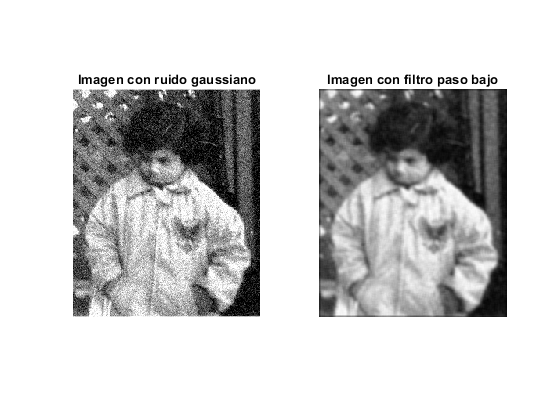

h1 = 1/25 * [1 1 1 1 1; 
             1 1 1 1 1;
             1 1 1 1 1;
             1 1 1 1 1;
             1 1 1 1 1] ; % definición de la máscara
N_pasoBajo = filter2(h1, N_gaussian);
N_pasoBajo_double = im2double(N_pasoBajo)/255;

figure;
subplot(1,2,1); imshow(N_gaussian);        title('Imagen con ruido gaussiano');
subplot(1,2,2); imshow(N_pasoBajo_double); title('Imagen con filtro paso bajo');

-    un filtro paso bajo en el dominio de la frecuencia, y

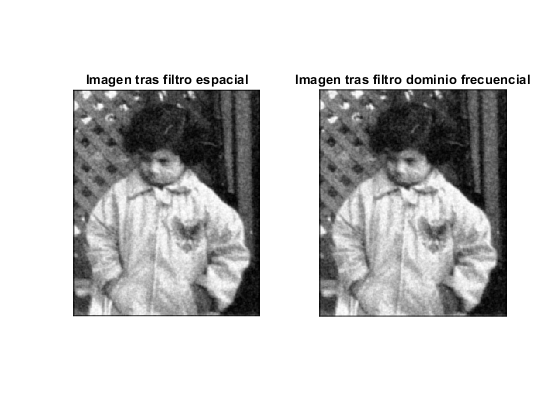

h2 = 1/9 * [1 1 1;
            1 1 1;
            1 1 1]; % definición de la máscara filtro paso bajo en el dominio espacial
N_gaussian_double = im2double(N_gaussian);
imagen_tras_filtro_espacial = filter2(h2, N_gaussian_double, 'full'); % filtrado en el dominio espacial

% filtrado equivalente en el dominio de la frecuencia
[M,N] = size(N_gaussian_double);
[P,Q] = size(h2);
tamano_filas_fft = M + P - 1;

% este es el tamaño en filas de la imagen tras la convolucion y sera el tamano en filas de su FFT
tamano_columnas_fft = N + Q - 1;

% este es el tamaño en columnas de la imagen tras la convolucion y sera el tamano en col. de su FFT
TF_imagen = fft2(N_gaussian_double, tamano_filas_fft, tamano_columnas_fft); % FFT de la imagen
TF_mascara = fft2(h2, tamano_filas_fft, tamano_columnas_fft);               % FFT de la mascara
TF_imagen_filtrada = TF_imagen.*TF_mascara;                                 % multiplico transformadas en el dominio de la frec.
imagen_tras_filtro_frecuencial = real(ifft2(TF_imagen_filtrada));           % con FFT inversa -> imagen filtrada

figure; 
subplot(1,2,1); imshow(imagen_tras_filtro_espacial);    title('Imagen tras filtro espacial');
subplot(1,2,2); imshow(imagen_tras_filtro_frecuencial); title('Imagen tras filtro dominio frecuencial');

-    un filtro gaussiano. Genérelo con fspecial y pruebe con diferentes valores de los parámetros.

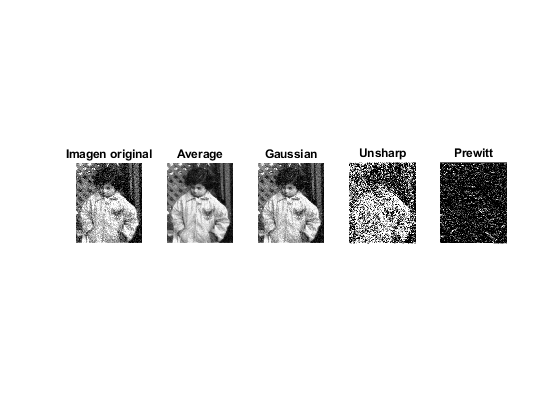

N_gaussian_double = im2double(N_gaussian);

h3 = fspecial('average');
h4 = fspecial('gaussian'); 
h5 = fspecial('unsharp');
h6 = fspecial('prewitt');

N_gaussian_average = filter2(h3, N_gaussian_double, 'same'); % same, valid
N_gaussian_gaussian = filter2(h4, N_gaussian_double, 'same');
N_gaussian_unsharp = filter2(h5, N_gaussian_double, 'same');
N_gaussian_prewitt = filter2(h6, N_gaussian_double, 'same');

figure;
subplot(1,5,1); imshow(N_gaussian_double);   title('Imagen original');
subplot(1,5,2); imshow(N_gaussian_average);  title('Average');
subplot(1,5,3); imshow(N_gaussian_gaussian); title('Gaussian');
subplot(1,5,4); imshow(N_gaussian_unsharp);  title('Unsharp');
subplot(1,5,5); imshow(N_gaussian_prewitt);  title('Prewitt');